new=tf([P_m I_m],[J P_m+B I_m])


new =
 
        0.1 s + 100
  ------------------------
  0.0033 s^2 + 3.1 s + 100
 
Continuous-time transfer function.



lowpass=tf([30],[1 30])


lowpass =
 
    30
  ------
  s + 30
 
Continuous-time transfer function.



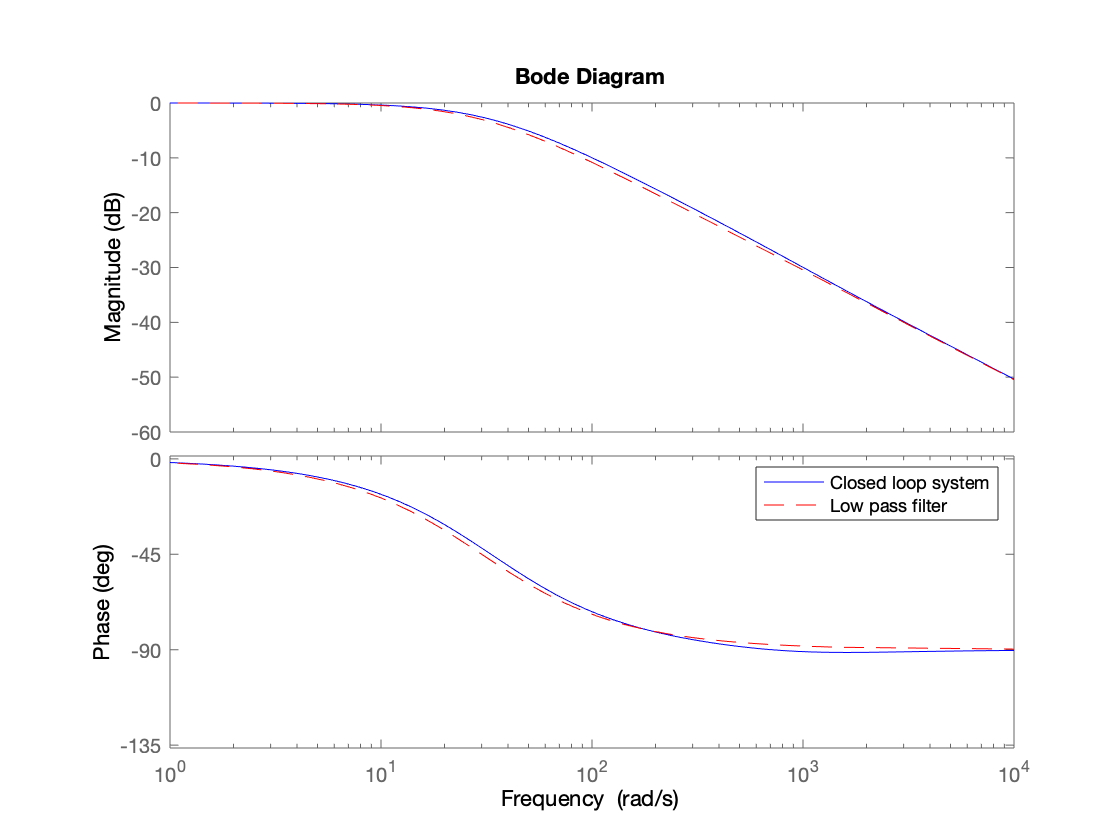

figure
bode(new,'b-',lowpass,'r--')
%h = legend({'$\frac{v\_{\mathrm{m}}}{v\_{\mathrm{d}}}$', '$\frac{ \omega\_{\mathrm{0}}}{s+\omega\_{\mathrm{0}}}$'},'Location','northeast'); set(h, 'Interpreter', 'latex');
h = legend({'Closed loop system','Low pass filter'},'Location','northeast');% set(h, 'Interpreter', 'latex');